# Regression Coefficient Example

This example shows how to compute regression coefficient matrices for Classical Least Squares (CLS), Principal Component Regression (PCR), and Partial Least Squares (PLS).

Copyright 2022-2023 Battelle Memorial Institute

## Supporting Information

### A Practical Guide to Chemometric Analysis of Optical Spectroscopic Data

Hope E. Lackey,$^{1,2}$ Rachel L. Sell,$^{1}$ Gilbert L. Nelson,$^{3*}$ Thomas A. Bryan,$^{4*}$ Amanda M. Lines,$^{1,2*}$ Samuel A. Bryan,$^{1,2*}$

$^{1}$ Pacific Northwest National Laboratory, 902 Battelle Boulevard, Richland, WA 99352 

$^{2}$ Washington State University, Department of Chemistry, Pullman WA 99164

$^{3}$College of Idaho, Department of Chemistry, 2112 Cleveland Blvd, Caldwell, ID 83605

$^{4}$ The MathWorks, 3 Apple Hill Drive, Natick, MA 01760-2098

*Email: sam.bryan@pnnl.gov Phone 1 509 375 5648; orcid.org/0000-0002-8826-0880

*Email: tbryan@mathworks.com Phone 1 508 647 7669

*Email: amanda.lines@pnnl.gov Phone: 1 509 375 5689

*Email: gnelson@collegeofidaho.edu Phone: 1 208 459 5241

## Compute Regression Coefficients

clearvars
load pnnl_napalm_data

Compute the regression coefficient matrices, $B$, for Classical Least Squares (CLS), Principal Component Regression (PCR), and Partial Least Squares (PLS).

[C_cls, B_cls] = pnnl_cls(A_train, C_train, A_unknown);

For PCR, use 3 principal components.  

[C_pcr, B_pcr] = pnnl_pcr(A_train, C_train, A_unknown, 3);

For PLS, use 3 latent variables.

[C_pls, B_pls] = pnnl_pls(A_train, C_train, A_unknown, 3);


Plot regression coeffcients for CLS.

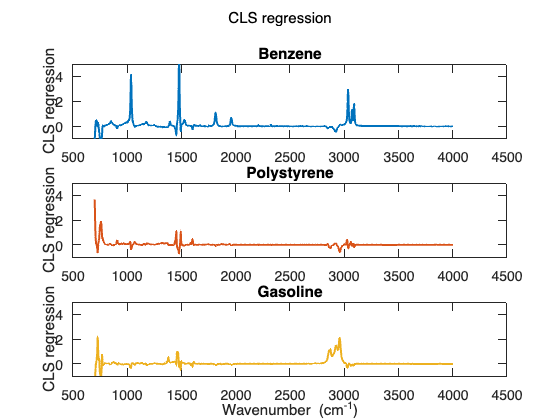

plot_regression_coefficients(B_cls,'CLS regression',Wavenumbers,WavenumberLabel,ConstituentNames)

Plot regression coeffcients for PCR.

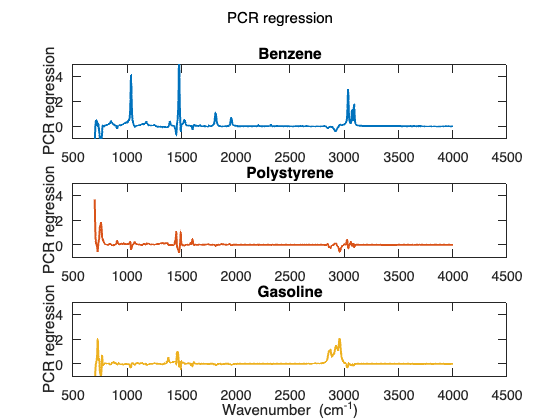

plot_regression_coefficients(B_pcr,'PCR regression',Wavenumbers,WavenumberLabel,ConstituentNames)

Plot regression coeffcients for PLS.

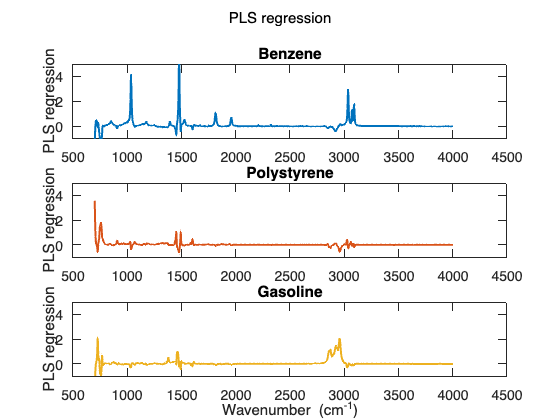

plot_regression_coefficients(B_pls,'PLS regression',Wavenumbers,WavenumberLabel,ConstituentNames)

function plot_regression_coefficients(B,y_label,Wavenumbers,WavenumberLabel,ConstituentNames)
    figure
    n = size(B,2);
    colorOrder = pnnl_colorOrder(n);
    figure;
    h = gobjects(1,n);
    for j = 1:n
        h(j) = subplot(n,1,j);
        plot(Wavenumbers,B(:,j),'LineWidth',2,'Color',colorOrder(j,:));
        title(ConstituentNames{j})
        ylabel(y_label)
    end
    sgtitle(y_label)
    linkaxes(h)
    xlabel(WavenumberLabel)
    set(h,'FontSize',14,'YLim',[-1 5]);
end

# Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830